clc;
clear;
close all;

NUM = 4;
dBTarget= -40;         %  Value to be changed

lB = ones(1, NUM);      % [1 1 1 1]
uB = 10 * ones(1, NUM); % [10 10 10 10]
p0 = ones(1, NUM);      % [1 1 1 1]

Optimizer Below

gamultiobj stopped because the average change in the spread of Pareto solutions is less than options.FunctionTolerance.


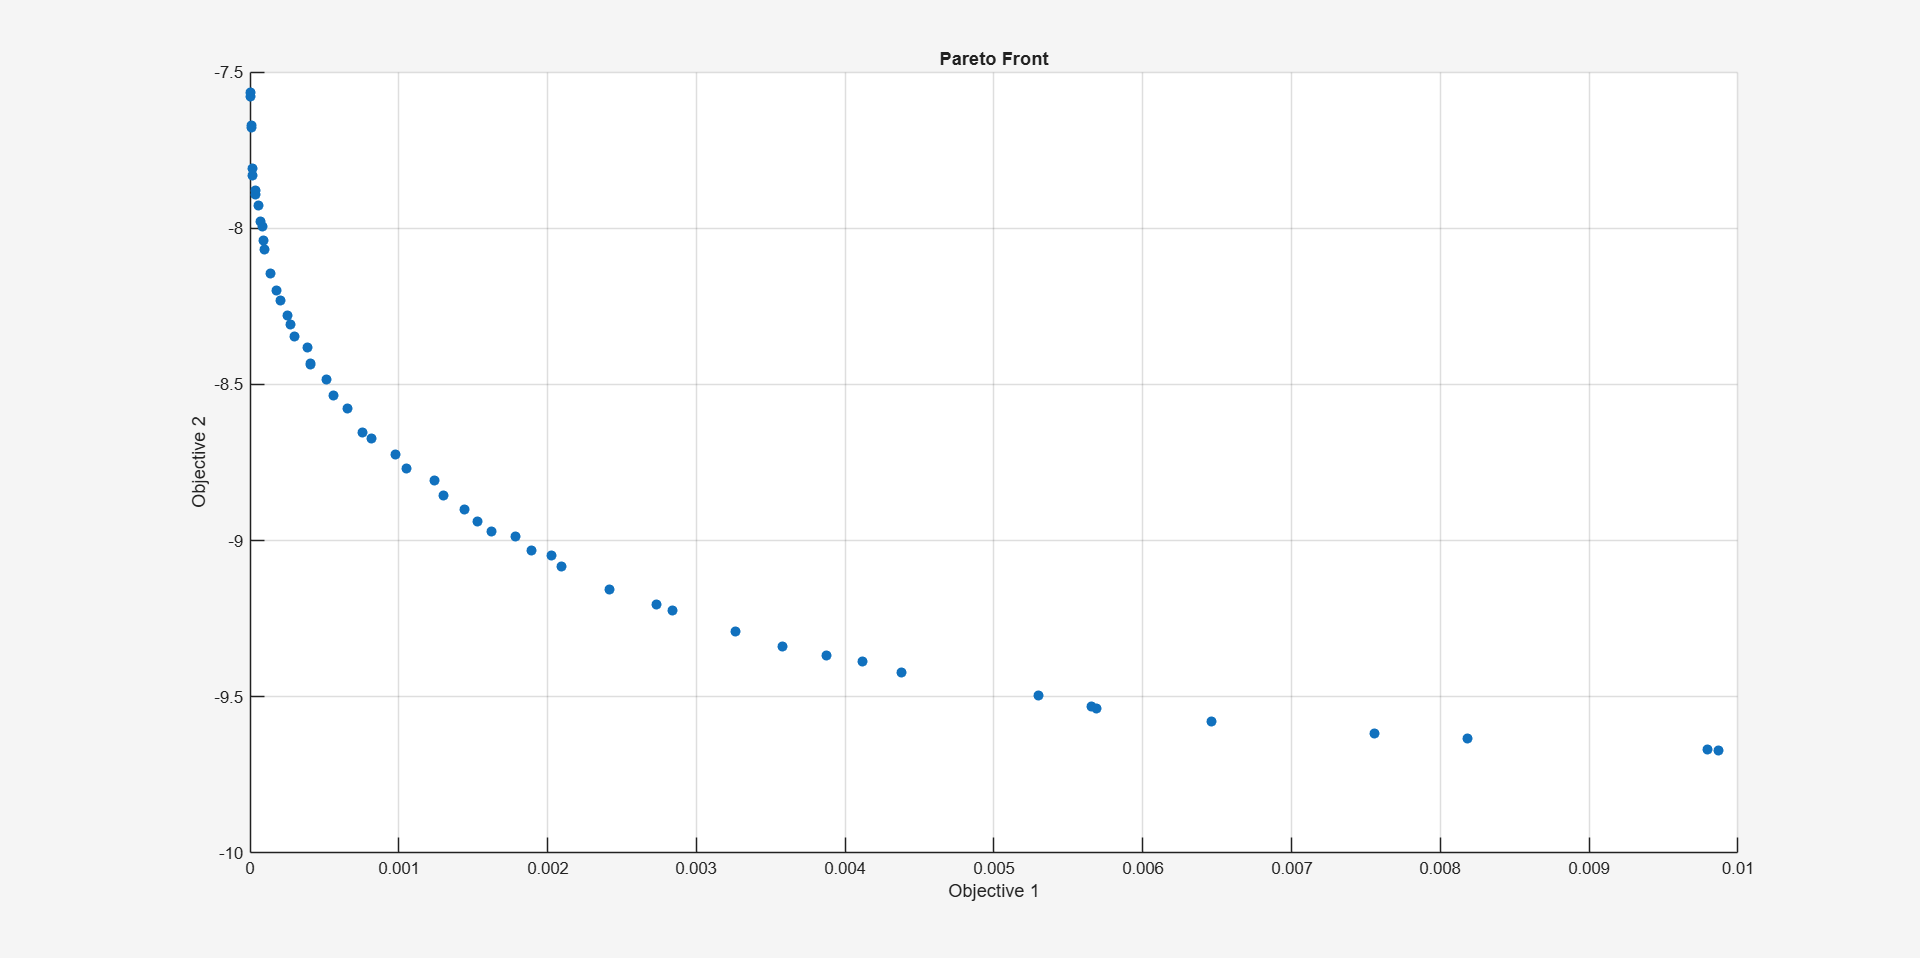

% Pass fixed parameters to objfun
objfun = @(p)SLL_error_and_D(p,dBTarget);

% Set nondefault solver options
options = optimoptions("gamultiobj","PopulationSize",70,"ParetoFraction",0.8,...
    "PlotFcn","gaplotpareto");

% Solve
[solution,objectiveValue] = gamultiobj(objfun,NUM,[],[],[],[],lB,uB,[],[],...
    options);


% Clear variables
clearvars objfun options

tag = abs(dBTarget);  % will convert -20 -> 20 for filenames

writematrix(objectiveValue, sprintf("results_SLL%d_objectivePareto.xlsx", tag));
writematrix(solution,        sprintf("results_SLL%d_currentsPareto.xlsx",  tag));

% optional cleanup
clearvars objfun options





